clear;clc
% block = 10000;
n = 4;
N = 2^n;
% SNR = 0.5:0.5:2.5;
% SNR = 2.5;
R = 0.5;
K = floor(N * R);
L = 4;

SNR_dB_start_Eb = 0;
SNR_dB_stop_Eb = 5;
SNR_points = 20;

SNR_dB_start_Es = SNR_dB_start_Eb + 10*log10(K/N);
SNR_dB_stop_Es = SNR_dB_stop_Eb + 10*log10(K/N);

sigma_start = sqrt(1/(2*10^(SNR_dB_start_Es/10)));
sigma_stop = sqrt(1/(2*10^(SNR_dB_stop_Es/10)));

sigmas = linspace(sigma_start, sigma_stop, SNR_points);

nb_errors = zeros(1, length(sigmas));
nb_errors_scl = zeros(1, length(sigmas));
nb_errors_map = zeros(1, length(sigmas));
% nb_bits = zeros(1, length(sigmas));
num = 200000;

% design_snr_dB = 0;
% SS = 10^(design_snr_dB/10);
% ZW = exp(-SS);
% Z = Bhattacharyya(N, ZW);
% [~, ordered] = sort(Z);
% Kselection = ordered(1:K);
% is_info = zeros(1, N);
% is_info(Kselection) = 1;
G = G_N(n);

for i = 1: SNR_points
    sigma_i = sigmas(i);
    U_info = randi([0, 1], num, K);
    U = zeros(num, N);
    % ZW = exp(-1/(2*sigma_i^2));
    % Z = Bhattacharyya(N, ZW);
    % [~, ordered] = sort(Z);
    % Kselection = ordered(1:K);
    % is_info = zeros(1, N);
    % is_info(Kselection) = 1;
    PW = beta_expansion(N);
    [~, ordered] = sort(PW, 'descend');
    Kselection = ordered(1:K);
    is_info = zeros(1, N);
    is_info(Kselection) = 1;
    codebook = generate_cb(is_info, G);
    U(:, Kselection) = U_info;
    X = mod(U * G, 2);
    S = 1 - 2 * X;
    Y = S + normrnd(0, sigma_i, [num, N]);
    LLR = 2 / (sigma_i^2) * Y;
    for j = 1: num
        U_hat = SC_decoder2(LLR(j, :)', is_info');
        U_hat_scl = SCL_decoder(LLR(j, :)', L, is_info');
        U_hat_map = MAP(codebook, Y(j, :), G);
        nb_errors(i) = nb_errors(i) + sum(U(j, :) ~= U_hat);
        nb_errors_scl(i) = nb_errors_scl(i) + sum(U(j, :) ~= U_hat_scl);
        nb_errors_map(i) = nb_errors_map(i) + sum(U(j, :) ~= U_hat_map);
    end
end
sc_ber = nb_errors / (num * K);
scl_ber = nb_errors_scl / (num * K);
map_ber = nb_errors_map / (num * K);


nnd_ber = [0.1205, 0.112875, 0.102875, 0.094, 0.08375, 0.07475, 0.06775, 0.056875, 0.0485, 0.04025, 0.0345, 0.02775, 0.02325, 0.0185, 0.01375, 0.0105, 0.0065, 0.0045, 0.002625, 0.001875];
nnd_ber_map = [0.115875, 0.1075, 0.0975, 0.08775, 0.077, 0.065125, 0.058625, 0.052125, 0.046, 0.038875, 0.033375, 0.02725, 0.021, 0.015875, 0.01225, 0.008625, 0.0065, 0.004625, 0.002875, 0.00125];

% nnd_ber
nnd_ber_beta = [0.12, 0.109125, 0.0995, 0.090125, 0.082625, 0.07525, 0.0665, 0.059, 0.051625, 0.0435, 0.0345, 0.028875, 0.022, 0.016625, 0.0125, 0.00825, 0.0055, 0.004125, 0.001875, 0.001125];
nnd_ber_map_beta = [0.11825, 0.109375, 0.10075, 0.089875, 0.08075, 0.072875, 0.064125, 0.057375, 0.049125, 0.042125, 0.033375, 0.029125, 0.02075, 0.016125, 0.01175, 0.00875, 0.0065, 0.0045, 0.00225, 0.00075];
nnd_ber_beta_llr = [0.119, 0.109375, 0.098875, 0.09025, 0.07975, 0.07225, 0.066, 0.058375, 0.048875, 0.04175, 0.0365, 0.028125, 0.021, 0.015125, 0.011375, 0.009, 0.0065, 0.004125, 0.0025, 0.0015];
nnd_ber_map_beta_llr = [0.112, 0.104375, 0.096625, 0.089125, 0.079125, 0.07, 0.06425, 0.0575, 0.050375, 0.04075, 0.0325, 0.026, 0.0215, 0.01525, 0.0105, 0.00875, 0.0065, 0.00375, 0.002625, 0.0015];

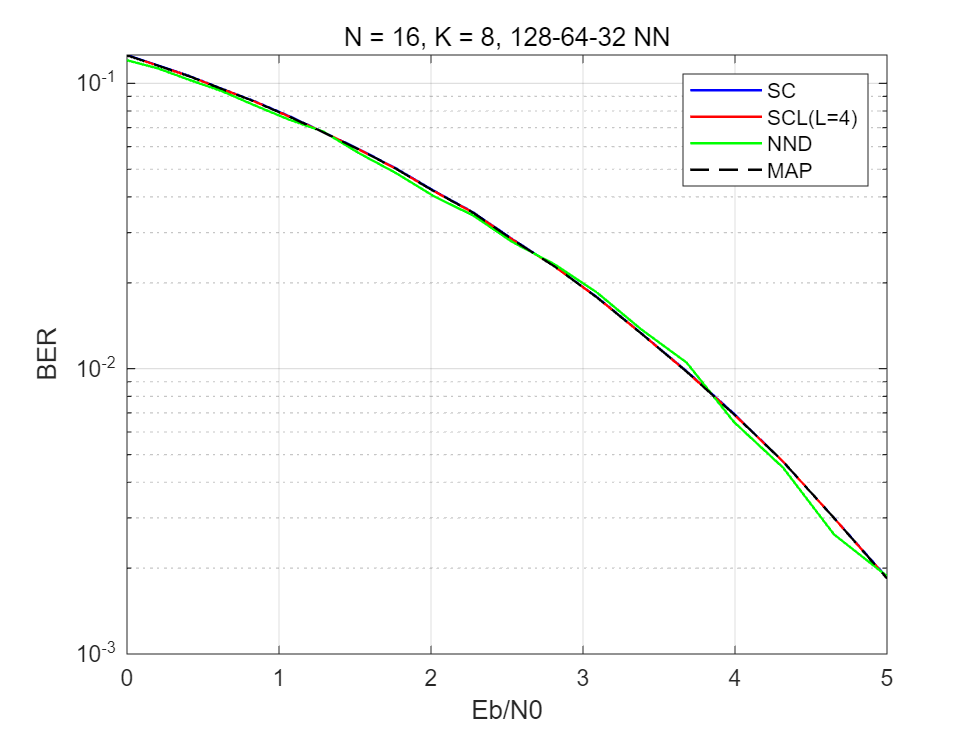

% sc,scl,nnd,map的对比
% sc_ber、scl_ber、nnd_ber、map_ber
EbN0 = 10*log10(1./(2*sigmas.^2)) - 10*log10(K/N); 
semilogy(EbN0, sc_ber, 'b-', EbN0, scl_ber, 'r-', EbN0, nnd_ber, 'g-', EbN0, map_ber, 'k--', LineWidth=1)
grid on
xlabel('Eb/N0'); ylabel('BER')
methods = {'SC', 'SCL(L=4)', 'NND', 'MAP'};
legend(methods);
title('N = 16, K = 8, 128-64-32 NN');

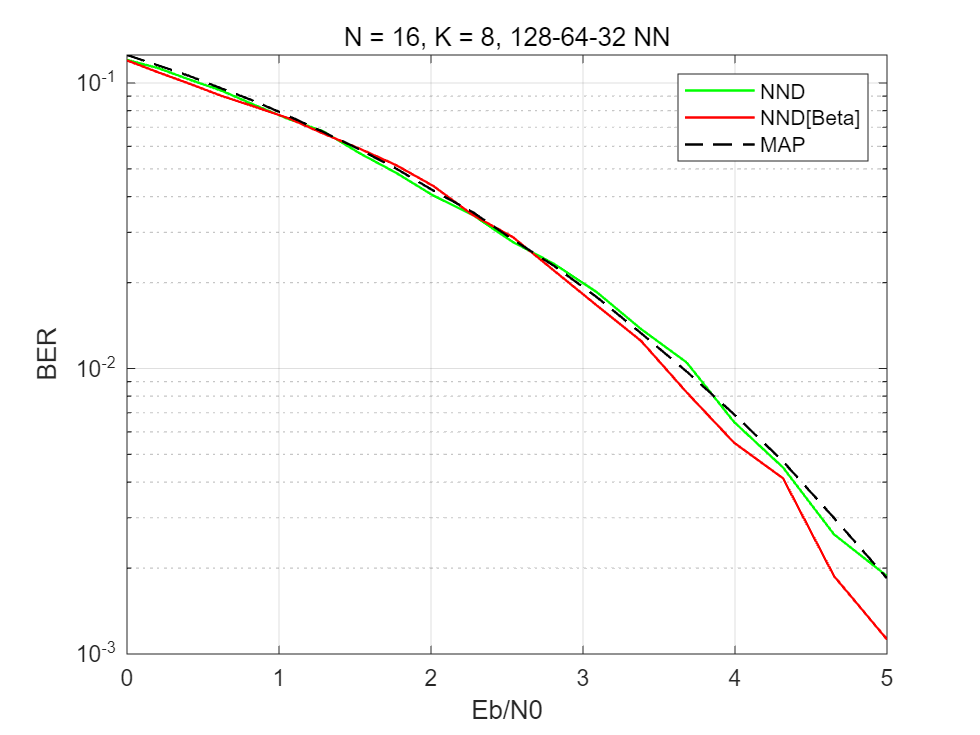

% nnd_ber、nnd_ber_beta，构造方式修改的对比
EbN0 = 10*log10(1./(2*sigmas.^2)) - 10*log10(K/N); 
semilogy(EbN0, nnd_ber, 'g-', EbN0, nnd_ber_beta, 'r-', EbN0, map_ber, 'k--', LineWidth=1)
grid on
xlabel('Eb/N0'); ylabel('BER')
methods = {'NND', 'NND[Beta]', 'MAP'};
legend(methods);
title('N = 16, K = 8, 128-64-32 NN');

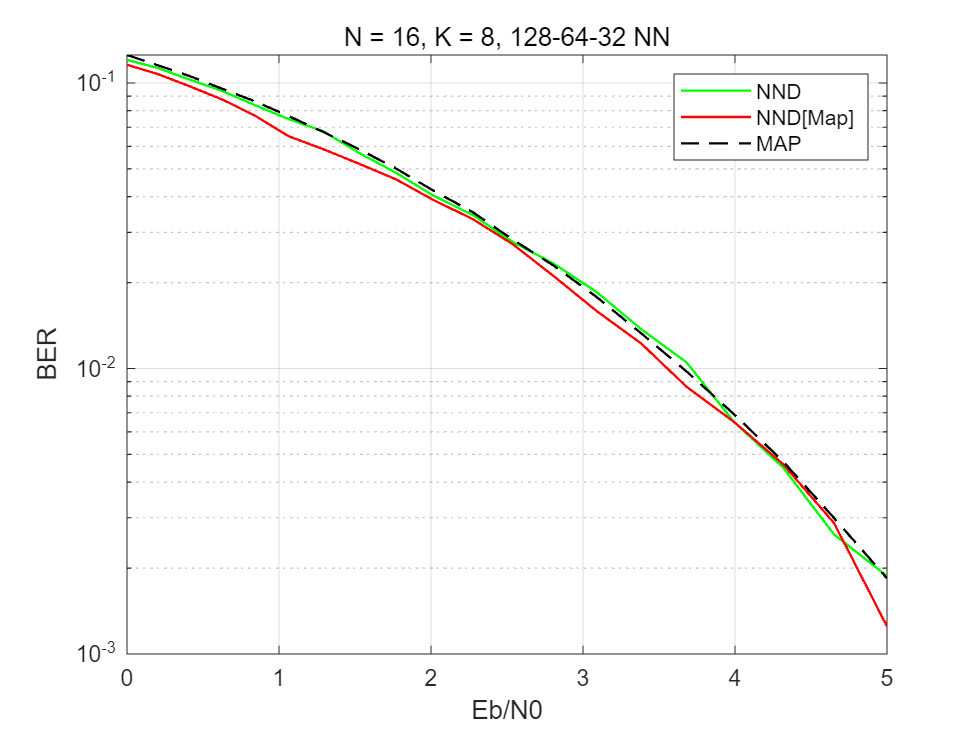

% nnd_ber、nnd_ber_map，label修改的对比
EbN0 = 10*log10(1./(2*sigmas.^2)) - 10*log10(K/N); 
semilogy(EbN0, nnd_ber, 'g-', EbN0, nnd_ber_map, 'r-', EbN0, map_ber, 'k--', LineWidth=1)
grid on
xlabel('Eb/N0'); ylabel('BER')
methods = {'NND', 'NND[Map]', 'MAP'};
legend(methods);
title('N = 16, K = 8, 128-64-32 NN');

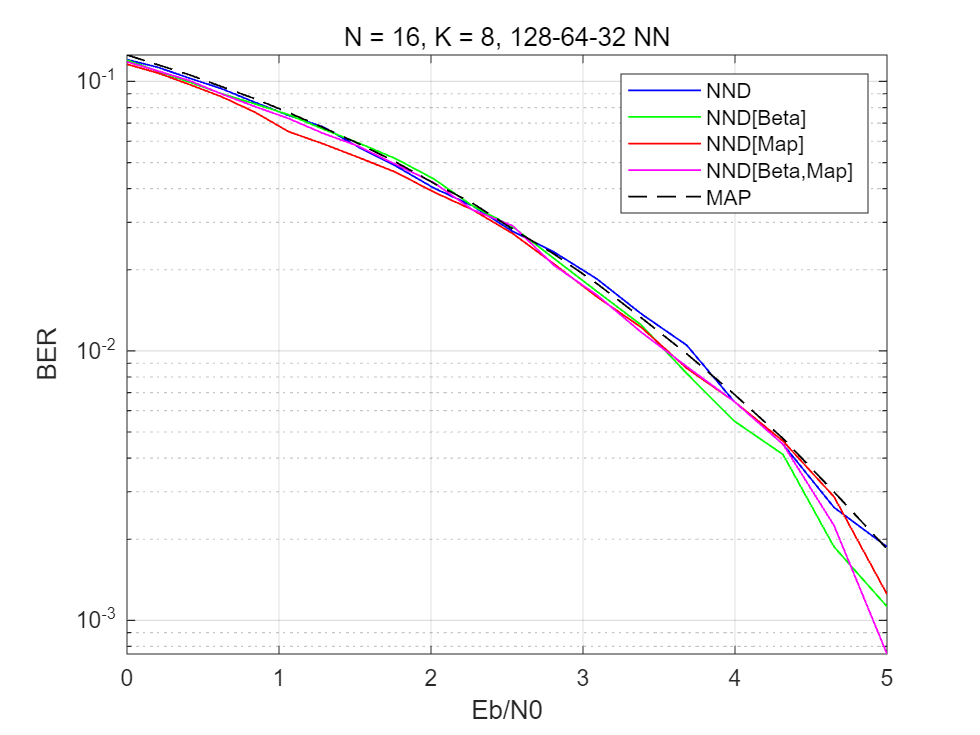

% nnd_ber、nnd_ber_beta、nnd_ber_map、nnd_ber_map_beta的对比
EbN0 = 10*log10(1./(2*sigmas.^2)) - 10*log10(K/N); 
semilogy(EbN0, nnd_ber, 'b-', EbN0, nnd_ber_beta, 'g-', EbN0, nnd_ber_map, 'r-', EbN0, nnd_ber_map_beta, 'm-', EbN0, map_ber, 'k--', LineWidth=0.75)
grid on
xlabel('Eb/N0'); ylabel('BER')
methods = {'NND', 'NND[Beta]', 'NND[Map]', 'NND[Beta,Map]', 'MAP'};
legend(methods);
title('N = 16, K = 8, 128-64-32 NN');